## [Classification with Machine Learning](https://apmonitor.com/pds/index.php/Main/ClassificationOverview)

Classification is the problem of identifying which set of categories based on observation features. The decision is based on a training set of data containing observations where category membership is known (supervised learning) or where category membership is unknown (unsupervised learning).

A basic example is to determine the number from pixelated images in a built-in sklearn dataset. The script predicts 0-9 from the following images with a Support Vector Classifier.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end
n_samples = length(imds.Files)

% Extract the images into a matrix
X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);


% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcecoc(array2table(im2double(X_Train)),Y_Train);
ypred = predict(classifier,array2table(im2double(X_Test)));

% Create a confusion matrix
figure;
confusionchart(Y_Test,ypred)

The confusion matrix shows the number of digits that are correctly classified and how the digits that are misclassified.

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);
figure;
imshow(imds.Files{n})
reshape(readimage(imds,n)',[1,28*28]);

% Predict number based on image
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Predicted:',yp])

The following are examples of different classification methods and how they compare to each other

[Classification - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/stats/classification.html)

**Support Vector**

% Fit model
lr = fitcecoc(tbl,"Y_Train",'Learners','svm');

% Predict values
lf_y = predict(lr,im2double(X_Test));
yp = predict(lr,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Support Vector Classifier Predicted:',yp])

% Calculate the Accuracy
C = confusionmat(lf_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

% Duration to fit
f = @() fitcecoc(tbl,"Y_Train",'Learners','svm');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)


**KNN**

% Fit model
knn = fitcecoc(tbl,'Y_Train',Learners='knn');

% Predict Values
knn_y = predict(knn,im2double(X_Test));
yp = predict(knn,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['K-Nearest Neighbros Predicted:',yp])

% Calculate the Accuracy
C = confusionmat(knn_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

% Duration to fit
f = @() fitcecoc(tbl,'Y_Train',Learners='knn');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

**Tree**

% Fit model
tree = fitcecoc(tbl,'Y_Train',Learners='tree');

% Predict Values
tree_y = predict(tree,im2double(X_Test));
yp = predict(tree,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Decision Tree Predicted:',yp])

% Calculate the Accuracy
C = confusionmat(tree_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

% Duration to fit
f = @() fitcecoc(tbl,'Y_Train',Learners='tree');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

**Discriminant**

% Fit model
dis = fitcecoc(tbl,'Y_Train',Learners='discriminant');

% Predict Values
dis_y = predict(dis,im2double(X_Test));
yp = predict(dis,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Distcriminant Predicted:',yp])

% Calculate Accuracy
C = confusionmat(dis_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

% Duration to fit
f = @() fitcecoc(tbl,'Y_Train',Learners='discriminant');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

**Neural Network**

% Fit model
net = fitcnet(tbl,"Y_Train");

% Predict Values
net_y = predict(net,im2double(X_Test));
yp = predict(net,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Neural Network Predicted:',yp])

% Calculate Accuracy
C = confusionmat(net_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

%Duration to fit
f = @() fitcnet(tbl,"Y_Train");
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

**Random Forest**

% Fit model
% Change NumTrees to view different accuracies
NumTrees = 40;
tbag = TreeBagger(NumTrees,tbl,'Y_Train');

% Predict Values
tbag_y = categorical(predict(tbag,im2double(X_Test)));
yp = predict(tbag,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Random Forest Predicted:',categorical(yp)])

% Calculate Accuracy
C = confusionmat(tbag_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

% Duration to fit
f = @() TreeBagger(NumTrees,tbl,"Y_Train");
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

In this case, the 28x28 (784) pixels are the input features to the classifier. The output of the classifier is a number from 0 to 9. The classifier is trained on 5000 images and tested on the other 50% of the data. This is an example of supervised learning where the data is labeled with the correct number. An unsupervised learning method would not have the number labels on the training set. An unsupervised learning method creates categories instead of using labels.

The first step in classification is to curate the data. This typically involves enumeratation, scaling, outlier detection, and splitting the data into training, test, and an optional validation set. One way to learn about classification methods is through concrete examples where the results are visualized as 2D data. The homogeneous data needs data labels (True/False) because there is no segregation of the data that is required for unsupervised learning methods.

## Generating data

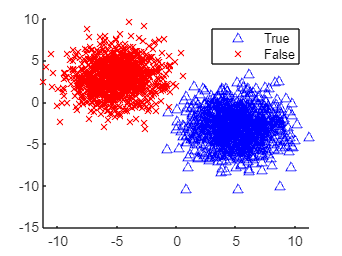

select_option = 6;

data_options = {'linear','quadratic','target','moons','circles','blobs'};
option = data_options{select_option};
n = 2000; % number of data points

X = rand(n,2);
mixing = 0.0; % add random mixing element to data
xplot = linspace(0,1,100);

if strcmp(option,'linear')
    y = false(n,1);
    for i=1:n
        if (X(i,1)+X(i,2))>=(1.0+mixing/2-rand(1)*mixing)
            y(i)=false;
        else
            y(i)=true;
        end
    end
    yplot=1-xplot;

elseif strcmp(option,'quadratic')
    % Initialize y and yplot
    y = false(1, n);
    
    % Compute y based on X values
    for i = 1:n
        if X(i,1)^2 >= X(i,2) + (rand()-0.5)*mixing
            y(i) = false;
        else
            y(i) = true;
        end
    end
    yplot = xplot.^2;
    y=y';

elseif strcmp(option,'target')   
    % Initialize y and yplot
    y = false(1, n);
    j = false;
    yplot = NaN(1, 100);
    
    % Compute y based on X values
    for i = 1:n
        if (X(i,1)-0.5)^2 + (X(i,2)-0.5)^2 <= 0.1 + (rand()-0.5)*0.2*mixing
            y(i) = false;
        else
            y(i) = true;
        end
    end
    
    % Compute yplot based on xplot values
    for i = 1:numel(xplot)
        r = 0.1 - (xplot(i)-0.5)^2;
        if r <= 0
            yplot(i) = NaN;
        else
            j = ~j; % plot both sides of circle
            yplot(i) = (2*j-1)*sqrt(r)+0.5;
        end
    end
    y=y';


elseif strcmp(option,'moons')
    [X,y] = twomoons(n);
    yplot = zeros(size(xplot));
    n = 4000;
elseif strcmp(option,'circles')
    [X,y] = twocircles(n);
    yplot = zeros(size(xplot));
    n = 4000;
elseif strcmp(option,'blobs')
    [X, y] = makeblobs(n,[5 -3; -5 3],2.0);
    yplot = zeros(size(xplot));
end    

% Plot the data

if ~ismember(option,{'circles'})
    figure;
    hold on;
    scatter(X(y > 0.5, 1), X(y > 0.5, 2), 'b', '^', 'DisplayName', 'True');
    scatter(X(y < 0.5, 1), X(y < 0.5, 2), 'r', 'x', 'DisplayName', 'False');
    if ~ismember(option, {'moons', 'blobs'})
        plot(xplot, yplot, 'k.', 'DisplayName', 'Division');
    end
else
    figure;
    hold on;
    gscatter(X(:,1),X(:,2),idx);
end
legend('show');


[trainInd,valInd,testInd] = dividerand(n,0.5,0,0.5);
XA = X(trainInd,:);
XB = X(testInd,:);
yA = y(trainInd,:);
yB = y(testInd,:);

% lr = fitclinear(XA,yA);
% lrp = predict(lr,XB);
% assess(lrp,XB,yB,option,xplot,yplot)

**Supervised Classification** 

`Logistic Regression`

% % Fit model
% lr = mnrfit(XA,yA);
% 
% % Predict Values
% lrp = predict(lr,xB);
% assess(lrp) 

`Discriminant`

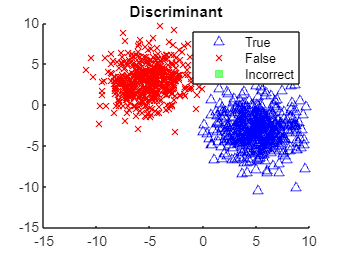

% Fit model
dis = fitcecoc(XA,yA,'Learners','discriminant');

% Predict Values
disp = predict(dis,XB);
assess(disp,XB,yB,option,xplot,yplot,'Discriminant')

`NaÃ¯ve Bayes`

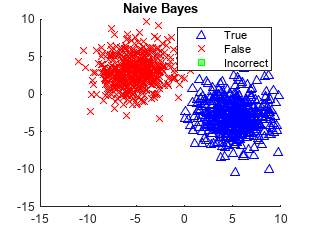

% Fit model
nb = fitcnb(XA,yA);

% Predict Values
nbp = predict(nb,XB);
assess(nbp,XB,yB,option,xplot,yplot,'Naive Bayes')

`K-Nearest Neighbors`

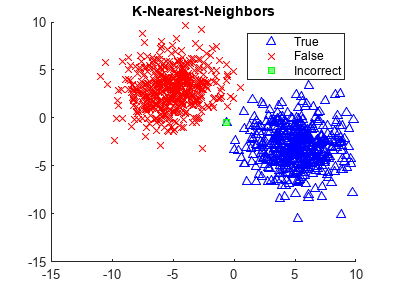

% Fit model
knn = fitcecoc(XA,yA,'Learners','knn');

% Predict Values
knnp = predict(knn,XB);
assess(knnp,XB,yB,option,xplot,yplot,'K-Nearest-Neighbors')

`Random Forest`

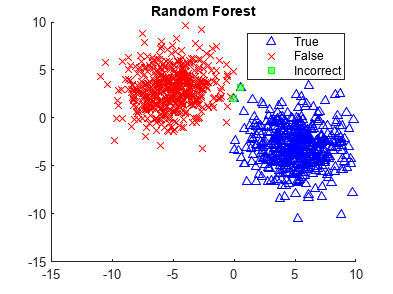

% Fit model
numTrees = 70;
rf = TreeBagger(numTrees,XA,yA);

% Predict Values
rfp_tmp = predict(rf,XB);
rfp = cellfun(@(x) logical(str2double(x)), rfp_tmp);
assess(rfp,XB,yB,option,xplot,yplot,'Random Forest')

`Support Vector Classifier`

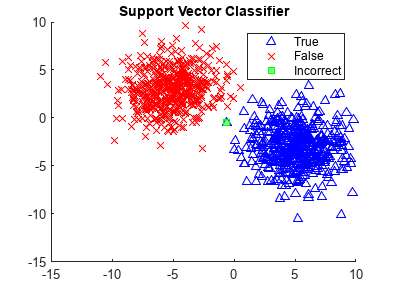

% Fit model
svm = fitcecoc(XA,yA,'Learners','svm');

% Predict Values
svmp = predict(svm,XB);
assess(svmp,XB,yB,option,xplot,yplot,'Support Vector Classifier')

`Neural Network`

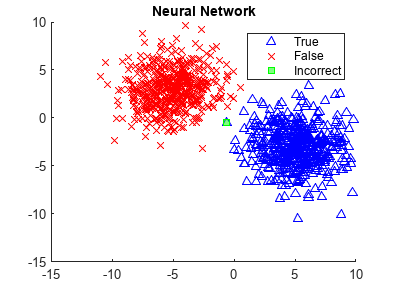

% Fit model
net = fitcnet(XA,yA);

% Predict Values
netp = predict(net,XB);
assess(netp,XB,yB,option,xplot,yplot,'Neural Network')

**Unsupervised Classification**

`K-Means Clustering`

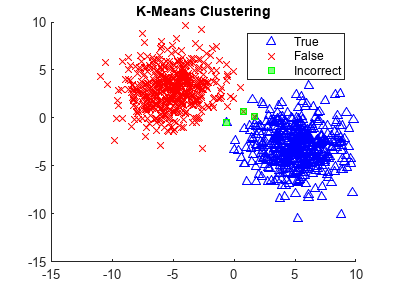

% Fit model
idx = kmeans(XA,2);

if idx(1) == 2
    idx = idx - 1;
end
if idx(1) == 0
    idx = flip(idx)
end
if idx(end) == 2
    idx = flip(idx) - 1;
end
    

assess(idx,XB,yB,option,xplot,yplot,'K-Means Clustering')

`Gaussian Mixture Model`

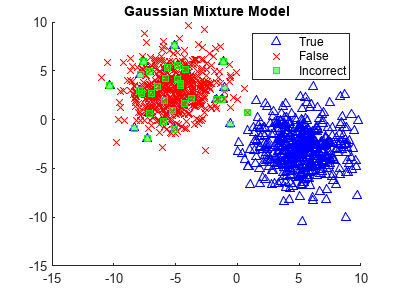

% Fit model
gmod = fitgmdist(XA,2);
idx = cluster(gmod,XA)-1;

if idx(1) == 2
    idx = idx - 1;
end
if idx(1) == 0
    idx = flip(idx);
end
if idx(end) == 2
    idx = flip(idx) - 1;
end

assess(idx,XB,yB,option,xplot,yplot,'Gaussian Mixture Model')

## Summary

Classification with machine learning is through supervised (labeled outcomes), unsupervised (unlabeled outcomes), or with semi-supervised (some labeled outcomes) methods. From the many methods for classification the best one depends on the problem objectives, data characteristics, and data availability. Above is a complete compilation of the source code for supervised and unsupervised learning methods. 

**Support Functions**

The function "twomoons" below is to generate moon-shaped data

[https://www.mathworks.com/help/stats/label-data-using-semi-supervised-learning-techniques.html](https://www.mathworks.com/help/stats/label-data-using-semi-supervised-learning-techniques.html)

function [X,label] = twomoons(n) % Generate two moons, with n points in each moon.
% Specify the radius and relevant angles for the two moons.
noise = (1/6).*randn(n,1);
radius = 1 + noise;
angle1 = pi + pi/10;
angle2 = pi/10;

% Create the bottom moon with a center at (1,0).
bottomTheta = linspace(-angle1,angle2,n)';
bottomX1 = radius.*cos(bottomTheta) + 1;
bottomX2 = radius.*sin(bottomTheta);

% Create the top moon with a center at (0,0).
topTheta = linspace(angle1,-angle2,n)';
topX1 = radius.*cos(topTheta);
topX2 = radius.*sin(topTheta);

% Return the moon points and their labels.
X = [bottomX1 bottomX2; topX1 topX2];
label = [ones(n,1); zeros(n,1)];
end

The function "twocircle" below is to generate moon-shaped data

function [X,idx] = twocircles(n) % Generate two moons, with n points in each moon.
% Specify the radius and relevant angles for the two moons.
r1 = 3;   % Radius of first circle
r2 = 6;   % Radius of second circle
theta = linspace(0,2*pi,n)';

X1 = r1*[cos(theta),sin(theta)]+ rand(n,1); 
X2 = r2*[cos(theta),sin(theta)]+ rand(n,1);
X = [X1;X2]; % Noisy 2-D circular data set
idx = spectralcluster(X,2)-1;
end


The function "makeblob" below is to generate blobbed data

function [X,y] = makeblobs(n,centers,cluster_std) % Generate two moons, with n points in each moon.
y = zeros(n, 1);
c1 = centers(1,:);
c2 = centers(2,:);


for i = 1:size(centers, 1)
    X((i-1)*n/size(centers, 1)+1:i*n/size(centers, 1), :) = bsxfun(@plus, cluster_std*randn(n/size(centers, 1), 2), centers(i,:));
    
    % Calculate the distance of each point to each cluster center
    d1 = sqrt(sum(bsxfun(@minus, X, c1).^2, 2));
    d2 = sqrt(sum(bsxfun(@minus, X, c2).^2, 2));
    % Assign labels based on distance to the nearest cluster
    y(d1 < d2) = true;
    y(d1 >= d2) = false;
end
end

function assess(P,XB,yB,option,xplot,yplot,tle)
    figure();
    scatter(XB(P==1,1), XB(P==1,2), 'Marker', '^', 'MarkerEdgeColor', 'blue', 'DisplayName', 'True');
    hold on;
    scatter(XB(P==0,1), XB(P==0,2), 'Marker', 'x', 'MarkerEdgeColor', 'red', 'DisplayName', 'False');
    scatter(XB(P~=yB,1), XB(P~=yB,2), 'Marker', 's', 'MarkerEdgeColor', 'green','MarkerFaceColor','green', 'MarkerFaceAlpha', 0.5, 'DisplayName', 'Incorrect');
    if ~any(strcmp(option, {'moons', 'circles', 'blobs'}))
        plot(xplot, yplot, '.', 'Color', 'black', 'DisplayName', 'Division');
    end
    title(tle);
    legend();
    hold off
end